[https://www.dailymail.co.uk/sciencetech/article-11149371/Over-HALF-people-regularly-play-video-games-experience-gamer-rage.html](https://www.dailymail.co.uk/sciencetech/article-11149371/Over-HALF-people-regularly-play-video-games-experience-gamer-rage.html) (people who rage)

clear;

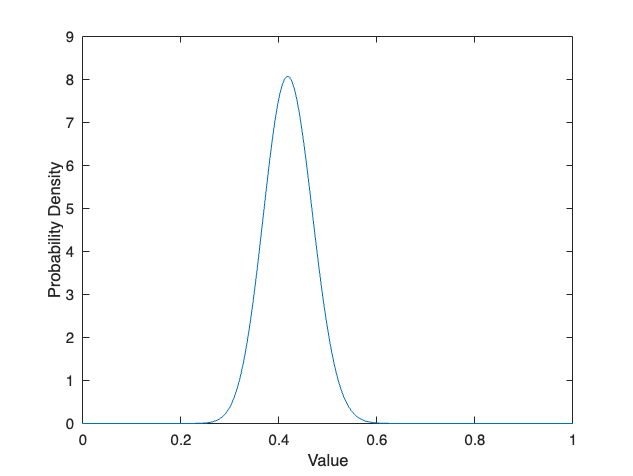

people = 5;
% Initialize distribution
a = 42; % First shape parameter
b = 58; % Second shape parameter
pd_beta = makedist('Beta', 'a', a, 'b', b);

% Visualize
x = linspace(0, 1, 200);
pr = pd_beta.pdf(x);
figure();
plot(x, pr)
xlabel('Value')
ylabel('Probability Density')

% title('Beta Distribution: a=8, b=8')

R = betarnd(42, 58, people, 1)

R =     0.4120
    0.4057
    0.4554
    0.5089
    0.3297


gameSize = 10;
baseAnger = .05;
angerWithEnemy = .2;

% 10 separate graphs for 10 games 
connections = group(gameSize, baseAnger, angerWithEnemy);

% There are 2 teams, so make a for loop that goes through it and strongly
% connects the one person to the other team

connections

connections =          0    0.0500    0.0500    0.0500    0.0500    0.2000    0.2000    0.2000    0.2000    0.2000
    0.0500         0    0.0500    0.0500    0.0500    0.2000    0.2000    0.2000    0.2000    0.2000
    0.0500    0.0500         0    0.0500    0.0500    0.2000    0.2000    0.2000    0.2000    0.2000
    0.0500    0.0500    0.0500         0    0.0500    0.2000    0.2000    0.2000    0.2000    0.2000
    0.0500    0.0500    0.0500    0.0500         0    0.2000    0.2000    0.2000    0.2000    0.2000
    0.2000    0.2000    0.2000    0.2000    0.2000         0    0.0500    0.0500    0.0500    0.0500
    0.2000    0.2000    0.2000    0.2000    0.2000    0.0500         0    0.0500    0.0500    0.0500
    0.2000    0.2000    0.2000    0.2000    0.2000    0.0500    0.0500         0    0.0500    0.0500
    0.2000    0.2000    0.2000    0.2000    0.2000    0.0500    0.0500    0.0500         0    0.0500
    0.2000    0.2000    0.2000    0.2000    0.2000    0.0500    0.0500    0.0


Angry = zeros(1,100);
% randomly sample from 1,100)
Angry(1) = 1

Angry =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


AngerRate = transpose(R)

AngerRate =     0.4120    0.4057    0.4554    0.5089    0.3297


%[Sh, Ih, Rh] = simulate_absir(M, Iv0, T recovery_rate)
numTimeSteps = 10; 
numGames = 10;
n = 100;  % Total number of elements
size = [10 10];  % Desired matrix dimensions
R = transpose(R);
IhOne = zeros(10);
state = zeros(100,numTimeSteps+ 1);
state(:,1) = Angry'

state =      1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0



for i = 1: numTimeSteps
    % one time step
    shuffle = randperm(n)
    matrix = reshape(shuffle, size);
    % R(matrix(:,i)); NEEDS TO BE USED LATER
    for game = 1:numGames
        shuffled_angry = state(matrix(:,game),i);

        % only Ih is important because we want to see how many people get
        % infected total
        % 2 because 1 is the base state, 2 is if one round went
        [sh, Ih, rh] = simulate_absir(connections, shuffled_angry, 2, 0); % recover rate is 0, they stay angry the whole time
        IhOne(:,game) = Ih(:,2);
        a = zeros(100,1);
        poop = shuffle'
        a(poop) = reshape(IhOne, 100,1)
        state(:,i+1) = a
    end
end

shuffle =     65    35    75    22    57    61    67    76    71    51    53    59    37    87    24    79    48    60    23    29    83    56    66    14    98    28    77    42    44    36    52    63    27    16     1    96    70    99    20    49    80    85    55    88    58    81    34     4    15     3


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =     65
    35
    75
    22
    57
    61
    67
    76
    71
    51


a =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


shuffle =      4     5    15    66    14    75    69    44    64    73    82    24    67    91    90    93    58    32    83    50    54     7    46    30    86    26    65    27    20    18    12    22     1    35    33    79    38    51    57    16     8    80    48    19    13    11    36    76    92    89


poop =      4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =      4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =      4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =      4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state =      1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop =      4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
     4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
     4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
     4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
     4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
     4
     5
    15
    66
    14
    75
    69
    44
    64
    73


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


shuffle = 1×100
    97    54    29    57    95    86    37    76    25    69    92    67    94    34    38    55    33    84    75    39     1    35    50    78    10     2    21     7    46    59


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    97
    54
    29
    57
    95
    86
    37
    76
    25
    69


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


shuffle = 1×100
    83    77    45    56     3    84    10    11    54    97    38     8    36    32    46     6    48     4    37    87    13    88    70    44    68    76    17    90    99    67


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     1     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     1     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


state = 100×11
     1     1     1     1     1     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    83
    77
    45
    56
     3
    84
    10
    11
    54
    97


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


shuffle = 1×100
    59    35    77    48    14     1    28    60   100     8    88    72    65    82    67    78    96    61    79    33    43    63    87     3    66     7    85    34    41    69


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     0
     1
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     0
     1
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


poop = 100×1
    59
    35
    77
    48
    14
     1
    28
    60
   100
     8


a = 100×1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


shuffle = 1×100
    10    44    59    64   100    15    56    43    24    33     7     8    11    95     4    65     1     2    94    85    42    26     5    30    74    57    16     6    47    31


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     0     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


poop = 100×1
    10
    44
    59
    64
   100
    15
    56
    43
    24
    33


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0


shuffle = 1×100
    24    59    30    73     6    17    51    82    87    65    25    97    34    41    22     5    67    64    43    14    20    84    53    86    99    32    79    54    58    96


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


poop = 100×1
    24
    59
    30
    73
     6
    17
    51
    82
    87
    65


a = 100×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0     0


shuffle = 1×100
    54    85    96    38    25    58    11     5    99     9    63    36    50    15    12    52    59    22    33    13    55    20    88    77    82    68    35    76    47    91


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


poop = 100×1
    54
    85
    96
    38
    25
    58
    11
     5
    99
     9


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     0     0


shuffle = 1×100
    36   100    58    79    40    27    20    83    32    60    48    70    22    71    34    78    81    94    85    44     4    68    96     1    76    84    59    33    61    19


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


poop = 100×1
    36
   100
    58
    79
    40
    27
    20
    83
    32
    60


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     0


shuffle = 1×100
    71    75    51    41    68    76   100    19    37    86    18    64    42     9     3    48    30     7    49    91    61    25    45    40    98    23    92    83    58    97


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     0
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


poop = 100×1
    71
    75
    51
    41
    68
    76
   100
    19
    37
    86


a = 100×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


state = 100×11
     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1     1


function [connections] = group(numPeople, baseAnger, angerWithEnemy)
    connections = ones(numPeople,numPeople) - eye(numPeople);
    connections = connections * baseAnger;
    for i = 1: numPeople/2
        for j = numPeople/2 + 1: numPeople
            connections(i,j) = angerWithEnemy;
        end
    end
    for i = numPeople/2+1: numPeople
        for j = 1: numPeople/2
            connections(i,j) = angerWithEnemy;
        end
    end
end
